# Calibration Results

## Analysis of the day 13/03

The data of 13/03 was recollected positioning the arm of the robot in random but difficult positions for the calibration. Different XYZ and RPY angles have been tried for every calib. Plus a final verification of the precision of the calibration method in these position is taken into account.

The calibration happens between the camera_0_color_optical_frame and the camera_1_color_optical_frame. Then a simple transform is performed to express camera_1_link wrt camera_0_color_optical_frame. The tf between gripper_left_link and camera_1_link is then listened and the results are stored in the following lines. Major concern is the rotation between the two reference frames which is the major cause of the displacement of the two Pointlcouds once they are united.

gripper_left_link(blue) and the )camera_1_link(green) 

clc
close all
clear all
%% %DATA
% 13/03/2023 "uncontrolled positions, mixed angles and positions" 
%gripper_left_link %camera_1_link
%checked and correct
T1_uncontrolled = [-0.0320037, -0.109751, -0.113909];
RPY1_uncontrolled = [-0.176643, 1.5364618, -1.7661877]; % order ZYX
Quat1_uncontrolled = [-0.4946 0.4884 -0.5146 0.5021]; % xyzw

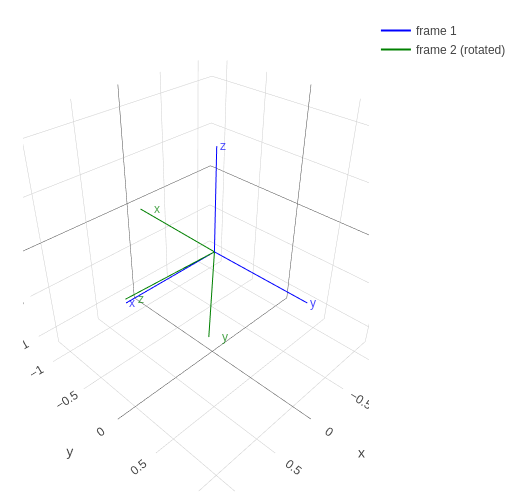

%checked and correct
T2_uncontrolled = [-0.018, -0.094, -0.117];
RPY2_uncontrolled = [0.075, 1.524, -1.543];
Quat2_uncontrolled = [0.500, 0.476, -0.523, 0.500] ; % xyzw

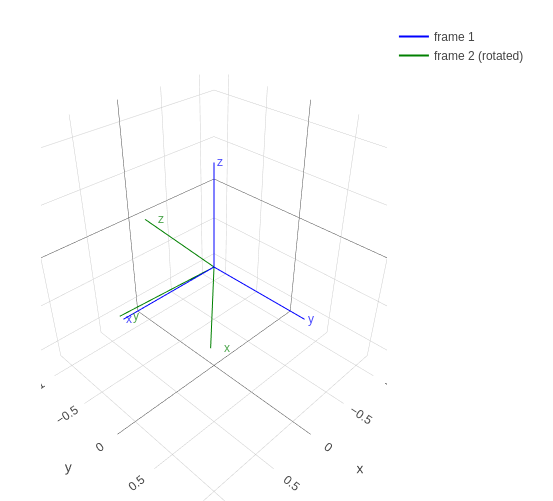

%checked and correct
T3_uncontrolled = [-0.012, -0.101, -0.127];
RPY3_uncontrolled = [0.306, 1.533, -1.310];
Quat3_uncontrolled =  [0.505, 0.477, -0.517, 0.500] ; % xyzw

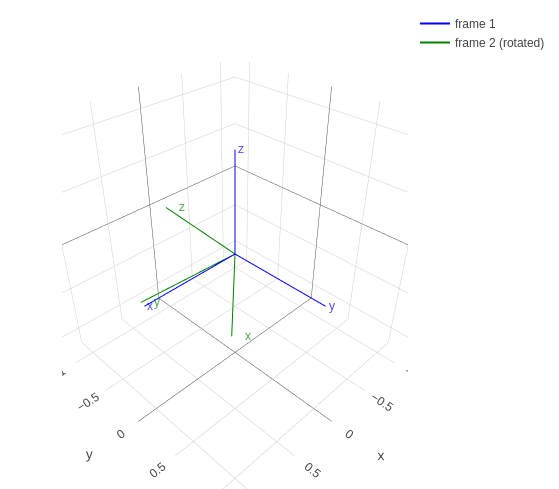

%checked and correct 
T4_uncontrolled = [-0.028, -0.090, -0.104] ;
RPY4_uncontrolled = [0.422, 1.533, -1.215];
Quat4_uncontrolled = [-0.511, -0.471, 0.521, -0.495] ; 

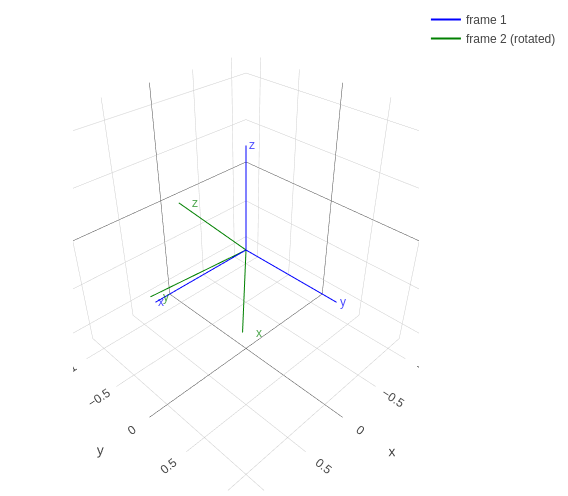

%checked and correct 
T5_uncontrolled = [-0.047, -0.113, -0.126] ;
RPY5_uncontrolled = [-2.671, 1.556, 1.991];
Quat5_uncontrolled =  [0.514, 0.492, -0.511, 0.482] ;

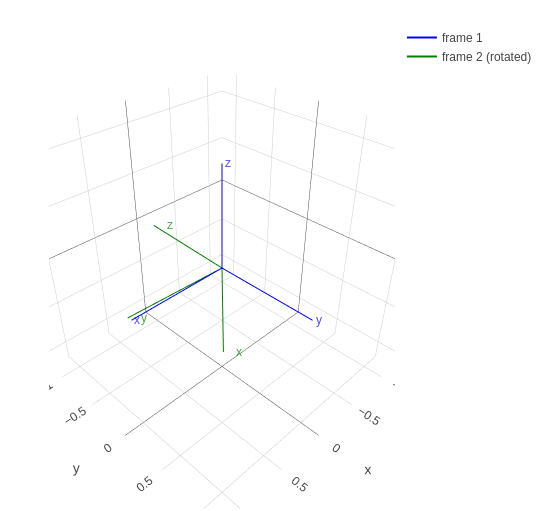0.

% checking errors on displacement and rotations
%% errors on displacement and rotations 13/03
T_matrix=[T1_uncontrolled;
          T2_uncontrolled;
          T3_uncontrolled;
          T4_uncontrolled;
          T5_uncontrolled];

T_vector_mean=[mean(T_matrix(:,1)),mean(T_matrix(:,2)),mean(T_matrix(:,3))]

T_vector_mean =    -0.0274   -0.1016   -0.1176


T_vector_std=[std(T_matrix(:,1)),std(T_matrix(:,2)),std(T_matrix(:,3))]

T_vector_std =     0.0135    0.0099    0.0095


RPY_matrix=[RPY1_uncontrolled;
            RPY2_uncontrolled;
            RPY3_uncontrolled;
            RPY4_uncontrolled;
            RPY5_uncontrolled];
% Deg_matrix=rad2deg(RPY_matrix);
Q_matrix=quaternion(RPY_matrix,'euler','ZYX','frame');
quatAverage = meanrot(Q_matrix); % finds mean rotation for quaternions
eulerAverage = euler(quatAverage,'ZYX','frame')

eulerAverage =     0.1277    1.5430   -1.4886


eulerAveraged = eulerd(quatAverage,'ZYX','frame')

eulerAveraged =     7.3194   88.4053  -85.2904


angularDistancerad_vector = 2*acos(abs(parts(quatAverage*conj(Q_matrix)))) % in radiants

angularDistancerad_vector =     0.0290
    0.0191
    0.0115
    0.0247
    0.0423


angularDistancedeg_vector = rad2deg(angularDistancerad_vector) %degrees

angularDistancedeg_vector =     1.6613
    1.0962
    0.6602
    1.4151
    2.4264


mean_of_diff_rad=mean(angularDistancerad_vector) % avarage angular distance

mean_of_diff_rad = 0.0253

std_rad=std(angularDistancerad_vector)

std_rad = 0.0115

mean_of_diff_deg=mean(angularDistancedeg_vector)

mean_of_diff_deg = 1.4519

std_deg=std(angularDistancedeg_vector)

std_deg = 0.6611

% double calibration to check error of the method in random pos by taking
% different pictures everytime ( position was rough )
calibT1_uncontrolled = [-0.390509760733171, -0.02734325523949511, -0.08091369880767295]; 
calibRPY1_uncontrolled = [0.3068 0.3489 0.5472];
calibQuat1_uncontrolled = [0.09855 0.2058 0.2375 0.9442] % xyzw

calibQuat1_uncontrolled =     0.0985    0.2058    0.2375    0.9442


calibT2_uncontrolled = [-0.4094332980192639, -0.031995695449533686, -0.07474587885799532];
calibRPY2_uncontrolled = [0.3124 0.3672 0.5491];
calibQuat2_uncontrolled = [0.09833 0.2151 0.2360 0.9425] % xyzw

calibQuat2_uncontrolled =     0.0983    0.2151    0.2360    0.9425


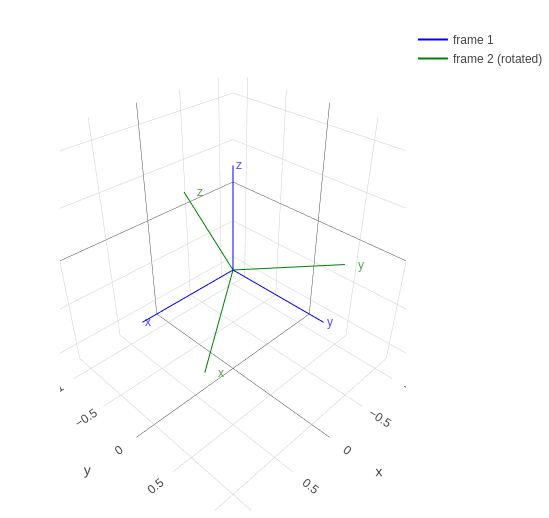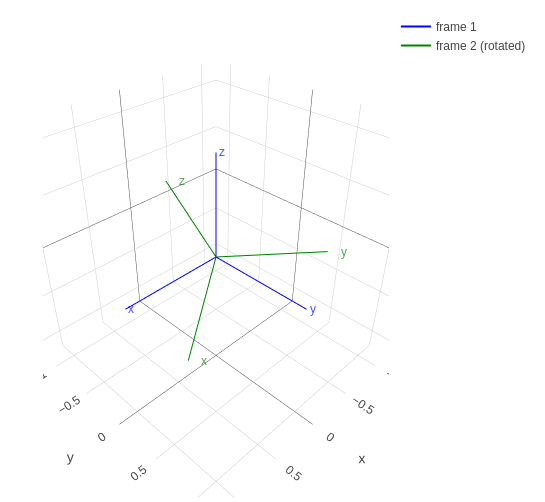

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPY1_uncontrolled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPY2_uncontrolled,'euler','zyx','frame');
%(https://es.mathworks.com/help/fusion/ref/quaternion.dist.html)
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0190

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 1.0907

%difference on displacement
diff_vector=abs(calibT1_uncontrolled-calibT2_uncontrolled)

diff_vector =     0.0189    0.0047    0.0062


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0204

#### Results:

1) Calibration at different points effectively result in very similar angle position

2)Multiple calibrations from different random position give a standard deviation of xyz[1.3 1 1] centimeters and of a 0.66 degree around a mean of 1.45deg.

3) The chosen method for calibration ( when done with random position which usually have a low alignment of the frames of the camera, gives back a displacement of a magnitude of two centimeters and a magnitude of one degree in rotation.

## Analysis of the day 14/03

The data of 14/03 was recollected positioning the arm of the robot in a known position with a tolerance for the arm displacement and rotation of 1mm and 1millidegree ( confirmed by listening to the tf ) . All the points have been given wrt to the xtion_rgb_optical_frame which is oriented the same as the camera_0_color_optical_frame but has a certain tf wrt the robot.

The first three calibrations have been done following a triangle with the arm parallel to the ground ( wrt gripper_left_link ) of which verteces changed in positions xyz:

Q123=[0 1 0 0 ] xyzw

P1=[-0.4 0 0 ]

P2=[-0.55 0.1 -0.2]

P3=[-0.3 -0.1 0.2]

The other three points have been chosen with the gripper link rotated of 30 degrees with respect to each angle ( Roll Pitch Yaw ):

P4=[-0.3 0.2 0 ]        Qroll=[-2.385 0.966 0 0 ] xyzw       RPYroll=[3.142 0 4.189]

P5=[-0.3 0.45 0.1 ]   Qpitch=[0 0.9658 0.2596 0] xyzw  RPYpitch=[2.6166 0 3.142]

P6=[-0.55 0 0.1 ]      Qpitch=[0 -0.966 0 0.2587] xyzw   RPYyaw=[3.142 -0.5233 3.142]

For every point chosen a double calibration has been made to estimate the displacement of the calibration, note that, differently from the data collected on 13/03, the arm has been placed near the camera_0 on the head so that the calibration sw could work with more accuracy (since the two frames comparted a bigger area )

### Result of Calibration /gripper_left_link  /camera_1_link

%% %DATA
% 14/03/2023 "controlled positions"
%gripper_left_link %camera_1_link
%checked and correct
T1_controlled = [-0.030, -0.102, -0.113];
RPY1_controlled = [0.684, 1.543, -0.9]; % order ZYX
Quat1_controlled = [0.502 0.487 -0.504 0.506]; % xyzw

T2_controlled = [-0.042, -0.101, -0.106];
RPY2_controlled = [0.484, 1.528, -1.106]; % order ZYX
Quat2_controlled = [0.500 0.481 -0.509 0.510]; % xyzw

T3_controlled = [-0.027, -0.105, -0.115];
RPY3_controlled = [-0.308, 1.542, -1.890]; % order ZYX
Quat3_controlled = [0.494 0.492 -0.512 0.502]; % xyzw

T4_controlled = [-0.041, -0.120, -0.120];
RPY4_controlled = [-0.4291, 1.553 -2.018]; % order ZYX
Quat4_controlled = [0.494 0.493 -0.513 0.5]; % xyzw

T5_controlled = [-0.039, -0.093, -0.111];
RPY5_controlled = [1.189, 1.542, -0.425]; % order ZYX
Quat5_controlled = [0.514 0.480 -0.507 0.499]; % xyzw

T6_controlled = [-0.016, -0.098, -0.103];
RPY6_controlled = [1.104, 1.522, -0.489]; % order ZYX
Quat6_controlled = [0.511, 0.478, -0.500, 0.511]; % xyzw

Same procedure as above

T_matrix=[T1_controlled;
          T2_controlled;
          T3_controlled;
          T4_controlled;
          T5_controlled;
          T6_controlled];

T_vector_mean=[mean(T_matrix(:,1)),mean(T_matrix(:,2)),mean(T_matrix(:,3))]

T_vector_mean =    -0.0325   -0.1032   -0.1113


T_vector_std=[std(T_matrix(:,1)),std(T_matrix(:,2)),std(T_matrix(:,3))]

T_vector_std =     0.0101    0.0092    0.0062


RPY_matrix=[RPY1_controlled;
            RPY2_controlled;
            RPY3_controlled;
            RPY4_controlled;
            RPY5_controlled;
            RPY6_controlled];
Q_matrix=quaternion(RPY_matrix,'euler','ZYX','frame');
quatAverage = meanrot(Q_matrix); % finds mean rotation for quaternions
eulerAverage = euler(quatAverage,'ZYX','frame')

eulerAverage =     0.5937    1.5434   -0.9983


eulerAveraged = eulerd(quatAverage,'ZYX','frame')

eulerAveraged =    34.0145   88.4329  -57.1994


angularDistancerad_vector = 2*acos(abs(parts(quatAverage*conj(Q_matrix)))) % in radiants

angularDistancerad_vector =     0.0084
    0.0160
    0.0263
    0.0238
    0.0274
    0.0283


angularDistancedeg_vector = rad2deg(angularDistancerad_vector) %degrees

angularDistancedeg_vector =     0.4817
    0.9173
    1.5090
    1.3628
    1.5671
    1.6209


mean_of_diff_rad=mean(angularDistancerad_vector)

mean_of_diff_rad = 0.0217

std_rad=std(angularDistancerad_vector)

std_rad = 0.0079

mean_of_diff_deg=mean(angularDistancedeg_vector)

mean_of_diff_deg = 1.2431

std_deg=std(angularDistancedeg_vector)

std_deg = 0.4514

### Checking difference on calibration for Point1

% double calibration Point1 ( easy position )
calibT11_controlled = [-0.3975, -0.0201, 0.1156] ; 
calibRPY11_controlled = [0.02300 -0.02554 0.01030];
calibT12_controlled = [-0.3976, -0.0189, 0.1114];
calibRPY12_controlled = [0.03927 0.000 0.01614];

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPY11_controlled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPY12_controlled,'euler','zyx','frame');
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0309

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 1.7692

%difference on displacement
diff_vector=abs(calibT11_controlled-calibT12_controlled)

diff_vector =     0.0001    0.0012    0.0042


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0044

### Checking difference on calibration for Point2

% double calibration Point2 ( easy position )
calibT21_controlled = [-0.5375, 0.0823, -0.1137] ; 
calibRPY21_controlled = [0.03927 -0.03146 0.01614];
calibT22_controlled = [-0.5365, 0.0820, -0.0945];
calibRPY22_controlled = [0.03893 -0.02823 0.01647];

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPY21_controlled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPY22_controlled,'euler','zyx','frame');
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0033

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 0.1870

%difference on displacement
diff_vector=abs(calibT21_controlled-calibT22_controlled)

diff_vector =     0.0010    0.0003    0.0192


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0192

### Checking difference on calibration for Point3

% double calibration Point3 ( easy position )
calibT31_controlled = [-0.2972, -0.1258, 0.3065] ; 
calibRPY31_controlled = [0.02174 -0.009088 0.01117];
calibT32_controlled = [-0.3032, -0.1237, 0.3127];
calibRPY32_controlled = [0.02875 -0.003398 0.008611];

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPY31_controlled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPY32_controlled,'euler','zyx','frame');
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0094

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 0.5370

%difference on displacement
diff_vector=abs(calibT31_controlled-calibT32_controlled)

diff_vector =     0.0060    0.0021    0.0062


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0089

### Checking difference on calibration for Roll position

(Note: the reference frames seen below are of camera_0_color_optical_frame and camera_1_color_optical_frame which have the z axis pointing outside of the face of the Tiago. RollPitchYaw are taken considering global coordinates.)


% double calibration Roll ( easy position )
calibTRoll1_controlled = [-0.2348, 0.1928, 0.11909] ; 
calibRPYRoll1_controlled = [0.02598 -0.001885 0.5341];
calibTRoll2_controlled = [-0.2299, 0.1925, 0.1219];
calibRPYRoll2_controlled = [0.02826 0.007582 0.5339];

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPYRoll1_controlled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPYRoll2_controlled,'euler','zyx','frame');
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0097

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 0.5581

%difference on displacement
diff_vector=abs(calibTRoll1_controlled-calibTRoll2_controlled)

diff_vector =     0.0049    0.0003    0.0028


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0057

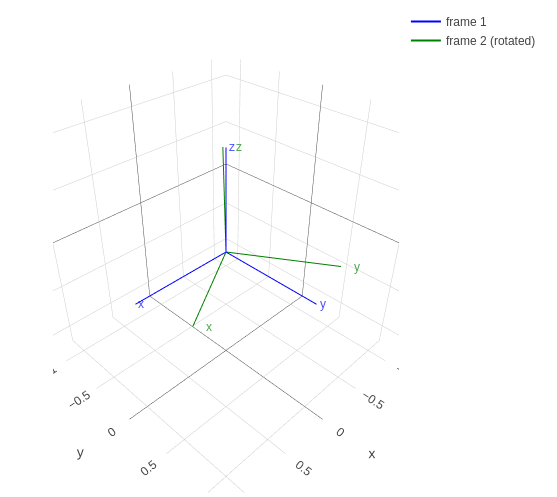

### Checking difference on calibration for Pitch position

% double calibration Pitch ( easy position )
calibTPitch1_controlled = [-0.2881, 0.3980, 0.1538] ; 
calibRPYPitch1_controlled = [0.5408 -0.03105 0.02263];
calibTPitch2_controlled = [-0.2906, 0.3975, 0.1506];
calibRPYPitch2_controlled = [0.5357 -0.04825 0.01758];

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPYPitch1_controlled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPYPitch2_controlled,'euler','zyx','frame');
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0187

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 1.0710

%difference on displacement
diff_vector=abs(calibTPitch1_controlled-calibTPitch2_controlled)

diff_vector =     0.0025    0.0005    0.0032


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0041

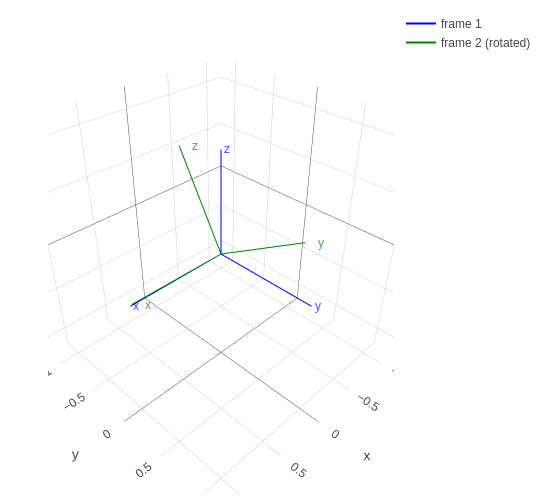

### Checking difference on calibration for Yaw position

% double calibration Yaw ( easy position )
calibTYaw1_controlled = [-0.5066, -0.01768, 0.19566]; 
calibRPYYaw1_controlled = [0.03206 -0.4810 0.02554];
calibTYaw2_controlled = [-0.5111, -0.01716, 0.1868];
calibRPYYaw2_controlled = [0.03255 -0.4701 0.02341];

% finding displacements and rotation differences
%difference on 3d rotation
q1=quaternion(calibRPYYaw1_controlled,'euler','zyx','frame'); % checked they are equal to the one found
q2=quaternion(calibRPYYaw2_controlled,'euler','zyx','frame');
angularDistancerad = 2*acos(abs(parts(q1*conj(q2)))) % in radiants

angularDistancerad = 0.0111

angularDistancedeg = rad2deg(angularDistancerad) % in degrees

angularDistancedeg = 0.6345

%difference on displacement
diff_vector=abs(calibTYaw1_controlled-calibTYaw2_controlled)

diff_vector =     0.0045    0.0005    0.0089


euclidean_dist=sqrt(sum((diff_vector) .^ 2))

euclidean_dist = 0.0100

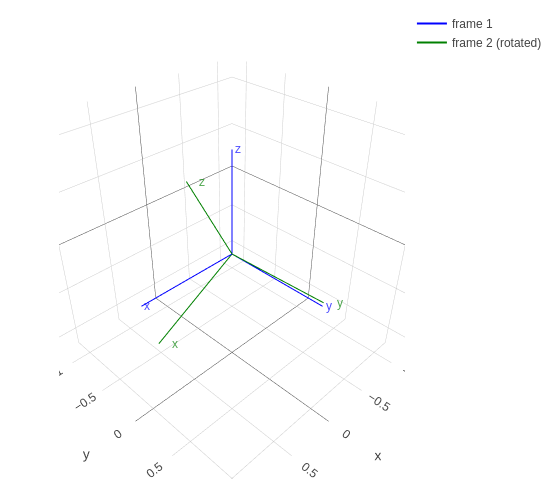

#### Results:

1) 